# Assignment #1: Quasi-static HEV model and Rule Based Control

## Group information

Group number: 46 

Students:

- Matteo Canestrini, s349238

- Dennis Bettinsoli, s357720

- Simone Massucco, s357725

## Load the cycle and vehicle data

In this report, a Rule-Based Control (RBC) strategy is developed and simulated in order to coordinate the power sources of a P2 parallel hybrid electric vehicle (HEV). This controller must determine the optimal torque-split factor ($$\alpha_{eng}$$) at each timestep to fulfill the driver's torque demand while minimizing fuel usage and maintaining the battery SOC within acceptable operational limits.

The main objectives of this assignment are the following:

- ***Implementation of a Rule-Based Control strategy***;

- ***Performance evaluation***;

- ***Analysis and comments***;

Briefly, the proposed strategy aims to evaluate the vehicle’s fuel consumption while accurately tracking the battery State of Charge (SOC) over a given driving mission, namely the *Worldwide Harmonized Light Vehicles Test Procedure* (***WLTP***). Furthermore, a rule-based power flow controller was designed to operate the internal combustion engine as close as possible to its Optimal Operating Line (OOL), in order to maximize the overall efficiency. Finally, the controller’s performance was assessed through the analysis of simulation results, with particular attention to its control logic, potential limitations, and any unexpected behaviors, for which possible improvements were proposed.

clear
close all
clc
addpath(genpath(fullfile("..", "Common")));

% Initialization
mission = load("WLTP.mat");                 % import the driving mission (WLTP)        
vehSpd = mission.speed_km_h ./ 3.6;         % vehicle speed in (m/s)
vehAcc = mission.acceleration_m_s2;         % vehicle acceleration in (m/s^2)
time = mission.time_s;                      % mission time in (s)


The simulation environment was initialized by clearing the workspace and loading the required folder about data, models and utilities functions. The driving mission, based on the WLTP cycle, was imported and processed in order to extract vehicle speed (*vehSpd*), acceleration (*vehAcc*), and time profiles, which *vehSpd* and *vehAcc* were used as exogenous inputs for the simulation. 

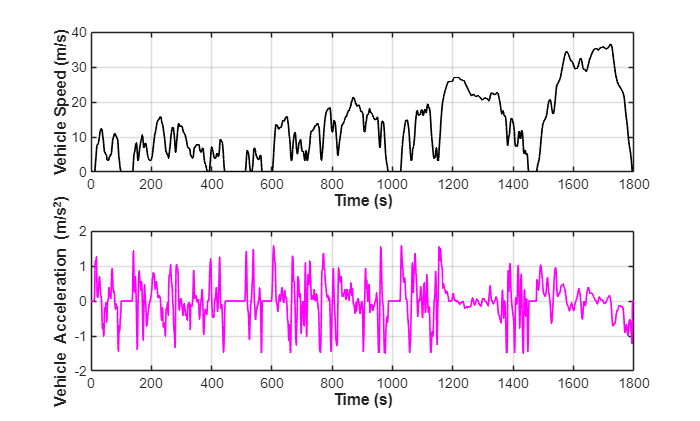


% plot canvas
l = tiledlayout(2,1);                   % figures layout

nexttile(1)
plot(time,vehSpd, 'LineWidth',1, "LineStyle","-",'Color',"k")
grid on, box on
xlabel("Time (s)","FontWeight","bold")
ylabel("Vehicle Speed (m/s)","FontWeight","bold")
xlim ([0 length(vehSpd)])

nexttile(2)
plot(time, vehAcc, "LineWidth",1, "LineStyle","-","Color","m")
grid on, box on
xlabel("Time (s)","FontWeight","bold")
ylabel("Vehicle Acceleration (m/s^2)","FontWeight","bold")
xlim ([0 length(vehAcc)])

These two plots show the exogenous inputs of the vehicle speed and acceleration, as functions of time.


veh = load("vehData.mat");                      % import the vehicle data
veh = scaleVehData(veh,118000,27000,2100);      % scale the data

load("transmControlData.mat");                  % import transmission control data


After that, the vehicle data were loaded and re-scaled to the desired specifications by adjusting the engine power (W), electric machine power (W), and battery capacity (Wh) parameters. Furthermore, the transmission control data were also imported in order to define the gear shifting strategy.

## Simulation loop

In this section, the simulation loop is defined to evaluate the vehicle's performance over the entire driving cycle. 

The simulation environment implements a single unified loop utilizing a *switch* statement (*controller_choice*) to dynamically select which rule-based controller to execute at each time step. The execution flow change automatically based on the user's selection: if the user input is 1, the script enter in the first case (*powerflowControl*) to execute the base controller and routes the final data into the *results.mat* file. While, if the selected input is 2, the script executes the function related to the extra feature #1 (*powerflowControlCooler*) and saves the output data into the r*esults_extra.mat* file. 

The use of this approach allows to not repeat the input data of the function related to the backward simulation model (*hev_model*) and the post-processing array assignments. Moreover, the switch function has been integrated with preallocation of data arrays, such as the gear number (GN) and the engine torque-split factor (engAlpha) before the simulation loop by using zeros() function. This approach allows to optimize code processes and to avoid the memory reallocation.

The dynamic system of the simulation loop is characterized by the following fundamental components:

- State Variable (**SOC**): the State of Charge of the battery (also denoted as $$\sigma$$);

- Control Variables: the engaged Gear Number (GN, also denoted as $$\gamma$$) and the engine torque-split factor ( engAlpha, also denoted as $$\alpha_{eng}$$);

- Exogenous Inputs: the vehicle speed (vehSpd) and acceleration (vehAcc) profiles, which are dictated by the driving mission;

- Cost Function: the total fuel consumption over the driving mission is represented by the engine's fuel mass flow rate ($$\dot{m}_{f}$$). 

The process begins by initializing the state variable and the starting gear number. A discrete-time loop then iterates through each timestep of the mission. At each step, the *gearControl* function determines the appropriate gear, while the custom *powerflowControl* algorithm computes the engine torque-split factor. In particular, the torque-split factor dictates the ratio between the engine torque and the total torque demand provided by the internal combustion engine, defined by the formula: $$\alpha_{eng}$$ = $$\frac{T_{eng}}{T_{dem}}$$. Furthermore, a more detailed explanation about the *powerflowControl* function is explained in the last part of this document.

% Initialization
SOC(1) = 0.6;     % Initial state variable (Battery State of Charge, sigma)
GN0 = 1;          % Initial gear number

% Preallocation arrays
GN = zeros(1, length(time));
engAlpha = zeros(1, length(time));

% Input: select the controller
controller_choice = input ("Select power flow control: 1 = base controller; 2 = enforce SOC controller\n")

controller_choice = 1


% Controller choice
if controller_choice == 1
    disp('>>> Running: Base Controller');
elseif controller_choice == 2
    disp('>>> Running: Extra feature #1 Controller');
else
    error('Warning: input not valid')
end

>>> Running: Base Controller



% --- MAIN SIMULATION LOOP ---
for n = 1 : length(time)
    % Determine the gear number based on vehicle speed
    GN(n) = gearControl(vehSpd(n), GN0, upSpd, downSpd);

    % Compute the torque-split factor using the custom RBC strategy

    switch controller_choice
        case 1 
            engAlpha(n) = powerflowControl(SOC(n),GN(n), vehSpd(n), vehAcc(n), veh);
        case 2 
            engAlpha(n) = powerflowControlCooler(SOC(n), GN(n), vehSpd(n), vehAcc(n), veh);
    end
    
    % Advance the simulation by one timestep using the HEV model
    [SOC(n+1), stageCost, unfeas, engPrf(n), emPrf(n), battPrf(n), vehPrf(n)] = ...
        hev_model(SOC(n), [GN(n), engAlpha(n)], [vehSpd(n), vehAcc(n)], veh);

    % Update the previous gear number for the next iteration
    GN0 = GN(n);
end


After the torque-split ratio estimation, these control variables are fed into the *hev_model *function, which updates the vehicle's state for the next timestep and calculates the associated stageCost (fuel consumption) along with the performance profiles of the various powertrain components. 

After the main simulation loop, the collected data arrays are reorganized into scalar structures to facilitate data manipulation and plotting.

% --- POST-PROCESSING ---
% Transform the non-scalar structs containing time profiles into scalar
% structs to make data manipulation and plotting easier.
engPrf = structArray2struct(engPrf);
emPrf = structArray2struct(emPrf);
battPrf = structArray2struct(battPrf);
vehPrf = structArray2struct(vehPrf);

% Pack all performance profiles into a single comprehensive structure
prof.emPrf = emPrf;     % Electric machine performances
prof.engPrf = engPrf;   % ICE performances
prof.battPrf = battPrf; % Battery performances
prof.vehPrf = vehPrf;   % General vehicle performances


Finally, a diagnostic routine is executed to identify any instances where the demanded torque exceeds the physical limits of the Internal Combustion Engine (ICE) or the Electric Machine (e-Machine). If such infeasibilities are detected, the system triggers a warning and saturates the recorded torque to its maximum physical capability for troubleshooting purposes.

% --- DIAGNOSTIC CHECKS ---
% Verify torque limits for the ICE and e-Machine torque requests 
for n = 1:length(time)
    % Re-evaluate the HEV model to extract the dynamic torque limits
    [~,~,~,~,~,~,~,~,engMaxTrq(n),emMaxTrq(n),emMinTrq(n)] = ...
        hev_model(SOC(n), [GN(n), engAlpha(n)], [vehSpd(n), vehAcc(n)], veh);
    
    % Check for ICE torque infeasibility
    if prof.engPrf.engTrqUnfeas(n) == 1
        prof.engPrf.engTrq(n) = engMaxTrq(n); % Saturate to maximum capability
        warning(['Torque unfeasibility reached by ICE at instant: %d \n '...
           'Engine Torque set at its maximum capability: %.2f (Nm)'], n, engMaxTrq(n))
    end

    % Check for e-Machine torque infeasibility
    if prof.emPrf.emTrqUnfeas(n) == 1
        prof.emPrf.emTrq(n) = emMaxTrq(n); % Saturate to maximum capability
        warning(['Torque unfeasibility reached by e-Machine at instant: %d \n '...
            'e-Machine Torque set at its maximum capability: %.2f (Nm)'], n, emMaxTrq(n))
    end
end

## Results analysis

In order to evaluate the effectiveness of the proposed RBC strategy, the simulation results are analyzed using both the standard post-processing tools provided in the given folders and a new plot is generated to a better percentage visualization of the operating modes distribution. By inspecting the power profiles, we can observe how the controller manages the driver's torque demand.

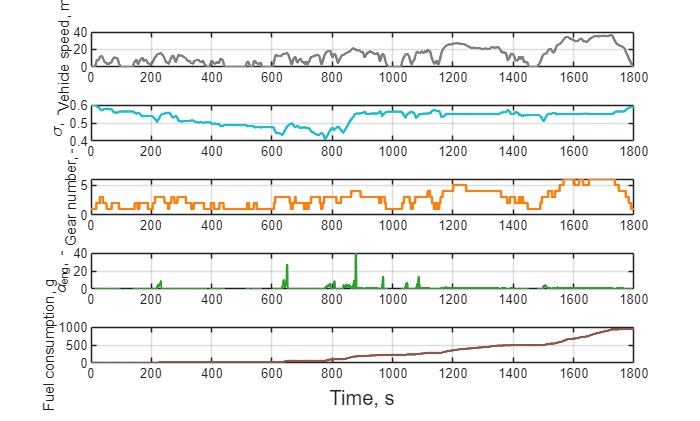

% Velocity, fuel consumption, SOC, gear profile
mainProfiles(prof);

In this first plot, using the *mainProfiles* function given as input the struct performance profile *prof* was used to generate the main analysis profiles (vehicle speed, current SOC, gear shifting number, torque-split factor, and fuel consumption).

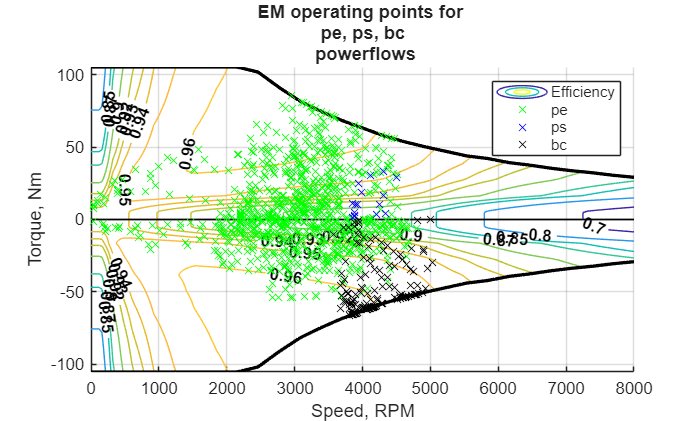

% Plot e-Machine operating points over its efficiency map
emMapWithPF(veh.em, prof);

In this other plot, the electric machine operating points over its efficiency map was depicted. This was analyzed through the *emMapWithPF* function. In particular, it is possible to see three different working modes:

- ***pe (***$$\alpha_{eng}$$ = 0***)***: stands for Pure Electric mode;

- ***ps (****0 <* $$\alpha_{eng}$$ < 1***)***: stands for Power Split mode;

- ***bc (***$$\alpha_{eng}$$ > 1***)***: stands for Battery Charging mode;

Mainly, a positive e-Machine torque indicates that the electric motor is providing traction, operating in either Pure Electric or Power Split mode. On the other hand, a negative e-Machine torque implies that it is acting as a generator. Under these conditions, it recharges the battery either through regenerative braking or via the active Battery Charging mode, as long as the battery SOC allows for it. Consequently, these working states are strictly dictated by the driver's torque demand and the vehicle dynamics.

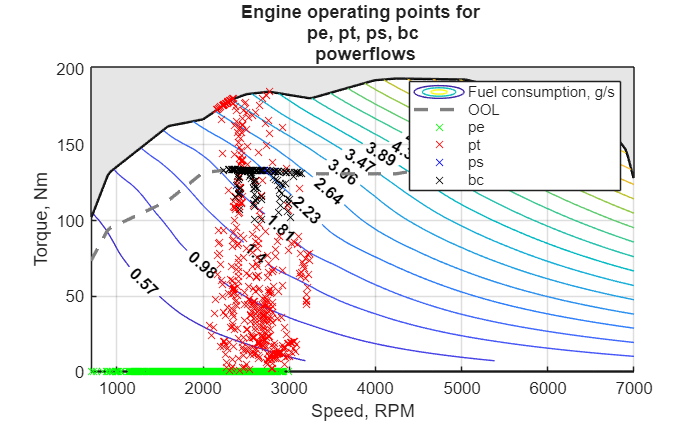

% Plot ICE operating points over the Fuel Consumption (FC) map 
engMapWithPF(veh.eng,prof,"fc","all");

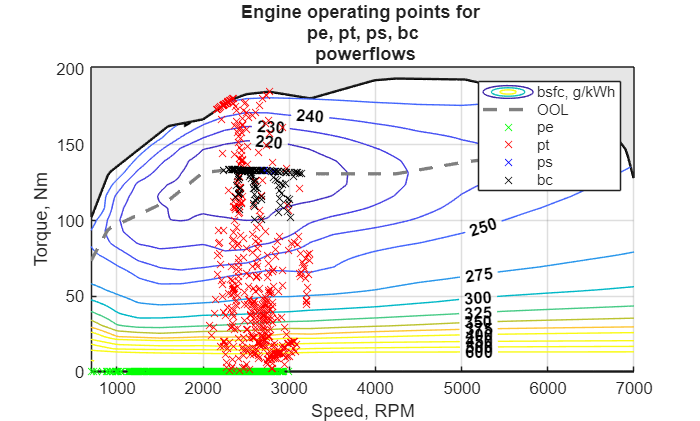

% Plot ICE operating points over the Brake Specific Fuel Consumption (BSFC) map
engMapWithPF(veh.eng,prof,"bsfc","all");

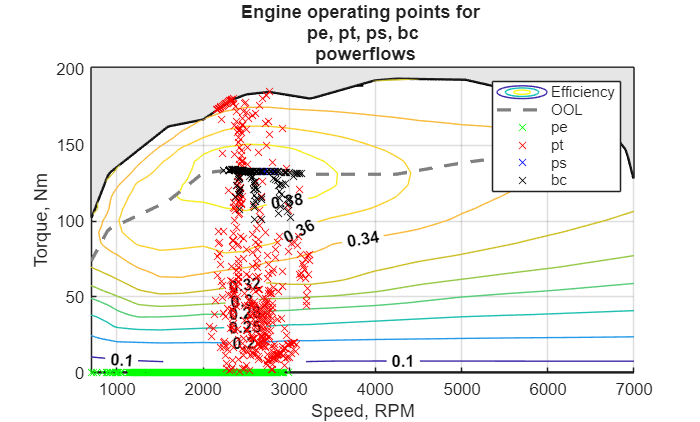

% Plot ICE operating points over the Efficiency (BSFC) map
engMapWithPF(veh.eng,prof,"eff","all");

In these three figures above, the ICE operating points were overlaid on the Fuel Consumption (FC), Brake Specific Fuel Consumption (BSFC), and Efficiency maps respectively using *engMapWithPF *tool. In this case, the plots highlight the controller's attempt to force the internal combustion engine to work near its Optimal Operating Line (OOL), but except if the speed is very low and the torque demand exceeds the OOL torque but the SOC is above some target.

The most remarkable feature of these operating maps is the placement of the Battery Charging ('*bc*', black crosses) points. They form a distinct horizontal cluster that perfectly tracks the OOL (the dashed grey line). This demonstrates that, when the battery requires charging, the controller does not blindly set a random $
$\alpha_{eng} > 1$$. Instead, it intelligently calculates $$\alpha_{eng} = T_{OOL} / T_{dem}$
$, forcing the engine to operate precisely at its maximum efficiency sweet spot (where efficiency $$> 36\%$
$, bsfc $$< 230$$ g/kWh). The excess torque is then successfully diverted to the battery.

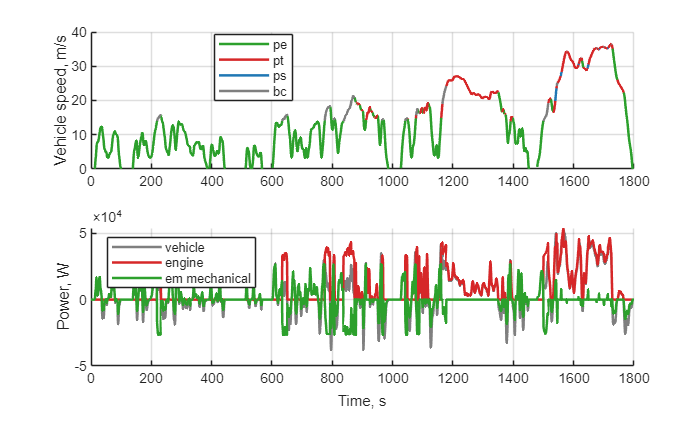

% Plot power profiles to inspect the 4 operating conditions
powerProfiles(prof);

The Pure Thermal ('*pt*', red lines) operating points exhibit a much wider vertical spread. Since $$\alpha_{eng} = 1$
$, the engine is strictly forced to follow the driver's demand. While a large concentration of these points falls within the high-efficiency central region, a significant portion drops into the lower-torque and lower-efficiency regions (efficiency $$< 25\%$
$, bsfc $$> 300$
$ g/kWh).

Instead, highlighted in blue ('*ps*', blue lines), the Power Split mode appears briefly during severe acceleration peaks where the engine alone would be inefficient, requiring the e-Machine to assist it (as ***torque-assist***).

% EXTRA PLOT 1: Operating Modes Distribution
% Calculate the time spent in each operating mode by analyzing the 'engAlpha' array

% Count the number of seconds for each condition
time_PE = sum(engAlpha == 0);                   % Pure Electric: alpha is exactly 0
time_PT = sum(engAlpha == 1);                   % Pure Thermal: alpha is exactly 1
time_PS = sum(engAlpha > 0 & engAlpha < 1);     % Power Split: alpha is between 0 and 1
time_BC = sum(engAlpha > 1);                    % Battery Charging: alpha is strictly greater than 1

To gain deeper insights into the controller's behavior and score additional insights into the power management logic, a custom pie chart was developed. This tool calculates the exact time spent in each of the four possible operating modes (as previously mentioned) by logically analyzing the *engAlpha* array. The control variable $$\alpha_{eng}$$ strictly defines the state of the powertrain.

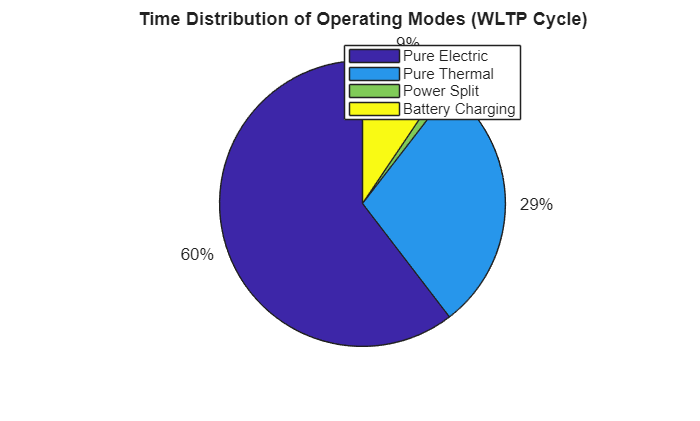

% Create the Pie Chart
figure
labels = {'Pure Electric', 'Pure Thermal', 'Power Split', 'Battery Charging'};
% The pie function automatically calculates the percentages based on the given array
pie([time_PE, time_PT, time_PS, time_BC]);
legend(labels)

title('Time Distribution of Operating Modes (WLTP Cycle)');

Overall, this RBC strategy performs remarkably well. The controller effectively executes a "load-leveling" strategy: it shuts down the ICE at low speeds (where ICE operating point is inherently inefficient) and locks the engine onto the OOL during battery charging phases to maximize fuel conversion efficiency. 

A critical control parameter that required careful calibration was the Pure Electric speed threshold ($$v_{pe}$$). Through an iterative trial-and-error process, the optimal value for this simulation was identified to be approximately 50 km/h. The sensitivity of the State of Charge to this parameter is significant: if $$v_{pe}$$ is set too high, the vehicle operates in electric mode for too long, causing a deep discharge and preventing the SOC from meeting its final target. Conversely, if $$v_{pe}$$ is set too low, the internal combustion engine is engaged prematurely, leading to an excessive accumulation of charge and overshooting the final SOC target at the expense of the overall fuel economy.

## Controller's limits & Future improvements

Unfortunately, while the charging logic is highly optimized, the Pure Thermal mode reveals a potential weakness. The wide spread of '*pt*' points in the low-efficiency region suggests that $$\alpha_{eng} = 1$$ is sometimes applied when the engine is thermally inefficient. To improve the strategy, the controller could be tuned to avoid the Pure Thermal mode entirely when the torque demand falls below a certain efficiency threshold. In such cases, the logic should either switch to Pure Electric (if SOC allows) or jump directly to Battery Charging to force the operating point back up to the OOL. 

Furthermore, the logic for $$\alpha_{eng}$
$during the battery charging phase could be made dynamic rather than static, adapting in real-time to the current engine speed to strictly lock the operating point exactly on the OOL.

## Save results

This final section of the script evaluates the overall performance of the powertrain over the WLTP cycle. The total fuel consumption (in kg) and the total traveled distance (in km) are calculated by integrating the instantaneous fuel flow rate and vehicle speed over time using the trapezoidal numerical integration method (`trapz`).

To evaluate the vehicle's efficiency using the standard European metric (liters per 100 kilometers), the total fuel mass is first converted into volume (liters) exploiting the specific fuel density provided in the engine data. The total volume is then normalized over the integrated distance.

Finally, the script extracts the final State of Charge (`finalSOC`) to verify the charge-sustaining effectiveness of the implemented rule-based strategy. All these key metrics are grouped and saved into the `results.mat` file for evaluation purposes, and subsequently printed to the console to provide immediate and readable feedback on the controller's performance. 

% Store results
if controller_choice == 1

    % 1. Calculate total fuel consumption in kg
    fuelConsumption = trapz(time,engPrf.fuelFlwRate)/1000; 
    
    % 2. Calculate total distance in km 
    distance = trapz(time, vehSpd) / 1000; 
    
    % 3. Calculate total fuel volume in liters
    fuel_volume = fuelConsumption / veh.eng.fuelDensity;
    
    % 4. Calculate fuel economy in l/100km
    fuelEconomy = (fuel_volume / distance) * 100; 
    
    % 5. Get final state of charge
    finalSOC = SOC(end); 
    
    % 6. Save results to .mat file
    save("results.mat", "prof", "fuelConsumption", "fuelEconomy", "finalSOC")

elseif controller_choice == 2
      % 1. Calculate total fuel consumption in kg
    fuelConsumption_extra = trapz(time,engPrf.fuelFlwRate)/1000; 
    
    % 2. Calculate total distance in km 
    distance = trapz(time, vehSpd) / 1000; 
    
    % 3. Calculate total fuel volume in liters
    fuel_volume_extra = fuelConsumption_extra / veh.eng.fuelDensity;
    
    % 4. Calculate fuel economy in l/100km
    fuelEconomy_extra = (fuel_volume_extra / distance) * 100; 
    
    % 5. Get final state of charge
    finalSOC_extra = SOC(end); 
    save("results_extra.mat", "prof", "fuelConsumption_extra", "fuelEconomy_extra", "finalSOC_extra")
else
    error('Warning: input not valid')
end 

% Calculate and display the total distance and fuel economy
if controller_choice == 1
    fprintf('The total distance is: %.2f km\n', distance);
    fprintf('The amount of fuel consumed is: %.2f kg',fuelConsumption)
    fprintf('Fuel Economy: %.2f l/100km\n', fuelEconomy);
    fprintf('Final State of Charge: %.2f\n', finalSOC);

elseif controller_choice == 2
    fprintf('The total distance is: %.2f km\n', distance);
    fprintf('The amount of fuel consumed is: %.2f kg',fuelConsumption_extra)
    fprintf('Fuel Economy: %.2f L/100km\n', fuelEconomy_extra);
    fprintf('Final State of Charge: %.2f\n', finalSOC_extra);
end

The total distance is: 23.26 km


The amount of fuel consumed is: 0.95 kg

Fuel Economy: 5.18 l/100km


Final State of Charge: 0.59


## **Final Comments and analysis**

By running both simulation, Improvements provided by the *enforce SOC controller *can be analyzed. From the pie charts, the operating modes distribution depict a reduction in the ICE usage, as the pure thermal percentage drops from $29\%$ to $24\%$.  In the meanwhile, the battery charging and the power split phases rise respectively from $9\%$ to $12\%$ and from $1\%$ to $6\%$. In this way, the power split operating mode, which was roughly not exploited by the base controller, provides an effective contribution to the consumption reduction.

The efficiency plots show that, with the enforce SOC controller implementation the ICE never works at operating points located over the OOL , this results in an enhancement of the consumptions, as the thermal engine can run closer to its optimal efficiency operating condition.

In addition, the power flow profiles display that, under severe vehicle conditions, e.g. over 70 km/h, the electric motor supplies the ICE, reducing the efforts. This can be noted by the activation of the power split mode, instead of the pure thermal mode in these situations. Furthermore, during deceleration phases at high speed, regenerative braking phases are more visible and this helps improving the charge-sustaining mode.

To sum up, the implementation of the enforce SOC controller contribute to an optimization of the fuel consumption. The amount of fuel consumed shrinks from 0.95 kg to 0.92 kg, resulting in an enhancement of the average consumption from 5.18 L/100km to 5.04 L/100km ( 2.7% reduction). Moreover, with the optimized controller the final SOC is closer to the target of 0.55: with the base controller the final SOC is 0.59, while in the second case is 0.57, leading to a better charge-sustaining strategy. 

## The torque-split controller

The function *powerflowControl* is a rule based strategy to minimize fuel consumption and to manage the battery State of Charge during a WLTP cycle. It defines in real-time the engine torque and the power-split factor depending on the driver demand, the SOC of the battery and the parameter *v_pe *(the pure electric velocity), i.e. the maximum speed for pure electric operations, which was properly tuned. 

The function receive as inputs the current SOC of the battery, the engaged gear number (GN), the vehicle speed (vehSpd) and acceleration (vehAcc) during the cycle and the data regarding the vehicle structure (veh), to take into account the car constraints. It provides as output the engine torque (T_eng) and the power-split factor (engAlpha), i.e. the ratio between the power provided by the ICE and the power demanded by the driver. 

Mainly, two parameters are tuned to manage the strategy:

- *v_pe:* the full electric speed, to force the car to operate at low-emission during urban scenarios, when the efficiency of the ICE is low;

- *SOC_target:* which is a reference level of the State of Charge to prevent battery depletion and to trigger battery charging when the SOC drops under the limit.

In addition, also 4 working conditions are implemented in this strategy:

- ***Full electric***: activated when the power demanded is null and when the vehicle speed is below the threshold;

- ***Power split:*** to let the ICE work at its optimum operating line, while the electric motor provides the remaining part of the torque demand. It is triggered when the torque demanded is high and the battery has sufficient charge to assist the ICE;

- ***Battery charging***: if the torque demand is low and the battery charge is low, the ICE torque is raised to match the optimum operating line;

- ***Pure thermal***: in all the other working conditions and when the demanded torque is high but the battery is too depleted to assist the engine.

To ensure the mathematical and physical robustness of the model, several input and output constraints have been implemented. Input checks trigger an error if nonphysical states are detected (e.g., negative speed, SOC out of [0, 1] bounds, or invalid gear numbers). Finally, an output check ensures that the requested engine torque is never negative, as the ICE cannot perform regenerative braking.

function [engAlpha, T_eng] = powerflowControl(SOC, GN, vehSpd, vehAcc, veh)

% POWER-FLOW-CONTROL
% Calculate engine torque split-factor alpha and engine torque based on vehicle performance.
%
% Input arguments:
%   SOC: double - current State of Charge of the battery
%   GN: double - current engaged gear
%   vehSpd: double - current vehicle speed (m/s)
%   vehAcc: double - current vehicle acceleration (m/s^2)
%   veh: struct - vehicle data structure
%
% Output arguments:
%   engAlpha: double - torque split factor of the engine (-)
%   T_eng: double - engine torque (Nm)

    % Load shaft speed and demanded torque from the drivetrain model
    [shaftSpd, T_dem, ~] = hev_drivetrain(vehSpd, vehAcc, GN, veh);

    % Collect engine torque optimal value (OOL) from vehicle data
    T_eng_ool = veh.eng.oolTrq(shaftSpd);

    % Calculate electric motor speed and its torque limits
    em_speed = shaftSpd * veh.em.tcSpdRatio;
    T_em_max = veh.em.maxTrq(em_speed);
    T_em_min = veh.em.minTrq(em_speed);

    % Optimization strategy: define starting parameters
    SOC_target = 0.55;               % Target State of Charge
    v_pe       = 50/3.6;             % Max speed for pure electric mode (m/s) - (TO BE TUNED)
    tau_tc     = veh.em.tcSpdRatio;  % Torque coupler speed ratio

    % Input control: to avoid <=0 and >=1 SOC values
    if SOC <= 0 
        error('Controller input warning: the Battery is discharged.\n SOC must be within 0 and 1. Input received: %.2f \n', SOC')
    elseif SOC >= 1
        error('Controller input warning: the Battery is overcharged.\n SOC must be within 0 and 1. Input received: %.2f \n', SOC)
    end

    % Input control: avoid negative speed
    if vehSpd < 0 
        error('Controller input warning: negative speed detected. The strategy is optimized for forward motion. Input received: %.2f \n', vehSpd)
    end

    % Input control: gear number
    if GN < 1 || GN > 6 || rem(GN,1) ~= 0
        error('Gear number must be a positive integer between 1 and 6. Input received: %.2f \n', GN)
    end

    % Logic Tree
    if T_dem <= 1  % not zero to avoid alpha -> infinite at low torque request
        % No traction required (standstill, coasting, or braking)
        T_eng = 0;    
    else
        if vehSpd < v_pe   
            % Pure electric mode at low speeds
            T_eng = 0;      
        
        elseif T_dem > T_eng_ool
            % High torque demand: check if battery can deploy energy
            if SOC > SOC_target
                % Power-split: engine works on OOL, EM provides the rest (respecting EM max limit)
                T_eng = max(T_eng_ool, T_dem - tau_tc * T_em_max);    
            else
                % Pure thermal: engine provides all torque to preserve battery
                T_eng = T_dem;    
            end

        elseif SOC < SOC_target
            % Low torque demand but battery needs charging
            % Battery charging: engine works on OOL, EM absorbs the excess (respecting EM min limit)
            T_eng = min(T_eng_ool, T_dem - tau_tc * T_em_min);    

        else 
            % Normal operation: pure thermal
            T_eng = T_dem;          
        end
    end 

    % Output control: avoid negative torque
    if T_eng < 0
        error('Negative torque requested. T_eng: %.2f Nm \n',T_eng)
    end

    % Final Alpha Calculation
    if T_dem < 0               
        engAlpha = 0;
    else
        engAlpha = T_eng / T_dem;
    end
end

## (Optional) A torque-split controller, with an extra feature

The powerflowControlCooler function implements an advanced rule-based strategy to compute the optimal engine torque split-factor $\alpha$ while enforcing strict constraints on the battery state of charge (*SOC*) to prevent long-term degradation. 

The input and the output arguments of the function are the same of function related to base controller (powerflowControl). First of all, the function evaluate the instantaneous physical state of vehicle. By passing the driving cycle inputs (vehicle speed, vehicle acceleration, engaged gear and the vehicle data) to the backward drivetrain model (*hev_drivetrain*), it allows to evaluate the crankshaft speed ($shaftSpd$) and the demanded torque ($T_{dem}$). Using the calculated shaft speed, it's possible to evaluate the optimal engine torque, by interpolating the Optimal Operating Line, from the vehicle data ($T_{OOL}$).

After that, the script executes the optimization strategy about extra feature #1: unlike the base controller function which only allocates a nominal SOC target , the enforce SOC strategy imposes two thresholds:

-  a minimum limit (**SOC_min** = 52%)

-  a maximum limit (**SOC_max** = 65%)

Furthermore the SOC thresholds, the SOC target ($SOC_{target}$) and the vehicle speed in pure electric ($v_{pe}$) are tuned to optimize the strategy; the target of state of charge has been chosen in order to stay between the SOC thresholds.

Once the boundary are established, the script executes the core of the logic tree: 

- **Pure Electric**: Engaged under conditions of one power demand, provided the vehicle speed remains below the threshold.

- **Battery Charging**: Battery needs charging when the current state of charge ($SOC$) is below the minimum limit of SOC ($SOC_{min}$); the engine operates on the OOL to satisfy traction while the electric machine absorbs the excess, respecting the EM torque limit. 

- **Max EM**: Max EM occurs when the current state of charge is above the SOC maximum limit ($SOC_{max}$); the EM torque operates at its peak, while the engine torque is activated only to cover the remaining torque deficit.

Once these critical safety checks are cleared, the strategy mirrors the baseline rule-based controller. Finally, as the base controller function, an output check ensures that the requested engine torque is never negative, as the ICE cannot perform regenerative braking.  

function [engAlpha, T_eng] = powerflowControlCooler(SOC, GN, vehSpd, vehAcc, veh)

% POWER-FLOW-CONTROL-COOLER (Extra Feature #1)
% Calculate engine torque split-factor alpha enforcing SOC thresholds.
%
% Input arguments:
%   SOC: double - current State of Charge of the battery
%   GN: double - current engaged gear
%   vehSpd: double - current vehicle speed (m/s)
%   vehAcc: double - current vehicle acceleration (m/s^2)
%   veh: struct - vehicle data structure
%
% Output arguments:
%   engAlpha: double - torque split factor of the engine (-)
%   T_eng: double - engine torque (Nm)

    % Load shaft speed and demanded torque from the drivetrain model
    [shaftSpd, T_dem, ~] = hev_drivetrain(vehSpd, vehAcc, GN, veh);
    
    % Collect engine torque optimal value (OOL) from vehicle data
    T_eng_ool = veh.eng.oolTrq(shaftSpd);
    
    % Calculate electric motor speed and its torque limits
    tau_tc = veh.em.tcSpdRatio;            % Torque coupler speed ratio
    em_speed = shaftSpd * tau_tc;          % Electrical machine speed (rpm) 
    T_em_max = veh.em.maxTrq(em_speed);    % Maximum electrical machine torque (Nm)
    T_em_min = veh.em.minTrq(em_speed);    % Minimum electrical machine torque (Nm)

    %Optimization strategy: Extra feature thresholds
    SOC_target = 0.55;       % Target SOC
    SOC_min    = 0.52;       % Min threshold of SOC ( 52% )
    SOC_max    = 0.65;       % Max threshold of SOC ( 65% )
    v_pe       = 50/3.6;    % Max speed for pure electric mode ( m/s )


    % Input control: to avoid negative and >1 SOC values
    if SOC < 0 || SOC > 1
        error('Controller input warning: SOC must be within 0 and 1. Input received: %.2f \n', SOC)
    end

    % Input control: avoid negative speed
    if vehSpd < 0 
        error('Controller input warning: negative speed detected. The strategy is optimized for forward motion. Input received: %.2f \n', vehSpd)
    end

    % Input control: gear number
    if GN < 1 || GN > 6 || rem(GN,1) ~= 0
        error('Gear number must be a positive integer between 1 and 6. Input received: %.2f \n', GN)
    end


    %Logic Tree - Extra feature #1
    if T_dem <= 1
        % No traction required
        T_eng = 0;     % Pure Electric
   
    elseif SOC < SOC_min 
        % SOC below threshold minimum -> Battery Charging: engine works on
        % OOL
        T_eng = min(T_eng_ool,T_dem - tau_tc * T_em_min);

    elseif SOC > SOC_max 
        % SOC above threshold maximum -> Max EM mode
        % Use Pure Electric where it is possible; if demand is too high,
        % use max EM and let engine cover the rest
        T_em  = min(T_dem / tau_tc, T_em_max);
        T_eng = max(0, T_dem - tau_tc * T_em);

    else
        % Normal Operation bounds (SOC between 40 % and 80 % )
        if vehSpd < v_pe
            % Pure Electric mode at low speeds
            T_eng = 0;

        elseif T_dem > T_eng_ool
            % Power split
            T_eng = max(T_eng_ool, T_dem - tau_tc*T_em_max);

        elseif SOC < SOC_target 
            % Battery Charging 
            T_eng = min(T_eng_ool, T_dem - tau_tc*T_em_min);

        else 
            % Pure Thermal
            T_eng = T_dem;
        end

    end 

    % Output control: avoid negative torque
    if T_eng < 0
        error('Negative torque requested. T_eng: %.2f Nm \n',T_eng)
    end

    % Final Alpha Calculation
    if T_dem < 0               
        engAlpha = 0;
    else
        engAlpha = T_eng / T_dem;
    end

 end